clearvars
close all
clc

osrm_data_sp = load('output_data\osrm_output_with_speed.mat').out;
aug_data = load('output_data\aug_output.mat').aug_data;
segments = load('input_data\osm.mat').osm;
markers = load('input_data\markers.mat').markers;
% adding distance from origin column to aug_out
[~,b] = ismember(aug_data.segment_id,segments.segment_id);
aug_data.distance_from_start = segments.distance_from_start(b);

corridor_length = 1e-3 * max(sum(segments(segments.dir==2,:).calc_length) , sum(segments(segments.dir==1,:).calc_length));
osrm_data_sp.Properties.VariableNames{10} = 'dir';
osrm_data_sp.Properties.VariableNames{11} = 'segment_id';
aug_data.Properties.VariableNames{2} = 'time';
osrm_data_sp.Properties.VariableNames{4} = 'time';

aux_segments = unique(aug_data.segment_id);
filter = NaN(size(aug_data,1),1);
for i=1:1:length(aux_segments)
    filter(aug_data.segment_id == aux_segments(i)) = isoutlier(aug_data(aug_data.segment_id == aux_segments(i),:).speed,'quartiles');
end
aug_data.filter = ~logical(filter);
size(aug_data,1)

ans = 114587

sum(filter)

ans = 2669


aux_segments = unique(osrm_data_sp.segment_id);
filter = NaN(size(osrm_data_sp,1),1);
for i=1:1:length(aux_segments)
    filter(osrm_data_sp.segment_id == aux_segments(i)) = isoutlier(osrm_data_sp(osrm_data_sp.segment_id == aux_segments(i),:).speed,'quartiles');
end
osrm_data_sp.filter = ~logical(filter);
size(osrm_data_sp,1)

ans = 114833

sum(filter)

ans = 3666

% osrm_data_sp = osrm_data_sp(~isnan(osrm_data_sp.speed),:);


sum(abs(osrm_data_sp.speed) >= 200)

ans = 44


osrm_data_sp.filter_speed_phy = true(size(osrm_data_sp,1),1);
osrm_data_sp.filter_speed_phy(abs(osrm_data_sp.speed) >= 200) = false;


a = findgroups(osrm_data_sp(:,{'arac_id','route_id'}));

osrm_data_sp.raw_acc = zeros(size(osrm_data_sp,1),1);

for i=1:1:max(a)
    aux_index = a == i;
    osrm_data_sp.raw_acc(aux_index) = (([diff(osrm_data_sp.speed(aux_index));NaN] * 1000 / 3600) ./ (osrm_data_sp.time_distance(aux_index)* 3600));
end

osrm_data_sp.filter_acc_phy = true(size(osrm_data_sp,1),1);
osrm_data_sp.filter_acc_phy(abs(osrm_data_sp.raw_acc) >= 10) = false;
sum(abs(osrm_data_sp.raw_acc) >= 10)

ans = 108


a = findgroups(osrm_data_sp(:,{'arac_id','route_id'}));
osrm_data_sp.phy_speed = NaN(size(osrm_data_sp,1),1);
osrm_data_sp.phy_acc = NaN(size(osrm_data_sp,1),1);

for i=1:1:max(a)
    aux_index = (a == i) & osrm_data_sp.filter_speed_phy & osrm_data_sp.filter_acc_phy;
    osrm_data_sp.phy_speed(aux_index) = 1e-3 * [diff(osrm_data_sp.distance_from_start(aux_index)) ./ hours(diff(osrm_data_sp.time(aux_index))); NaN];
    osrm_data_sp.phy_acc(aux_index) = ([(diff(osrm_data_sp.phy_speed(aux_index)) * 1000 / 3600) ./ seconds(diff(osrm_data_sp.time(aux_index))); NaN]);
end



osrm_data_sp.diff_speed = osrm_data_sp.speed - osrm_data_sp.phy_speed;
osrm_data_sp.diff_acc = osrm_data_sp.raw_acc - osrm_data_sp.phy_acc;

find(osrm_data_sp.diff_speed == max(osrm_data_sp.diff_speed))

ans = 92760


find(osrm_data_sp.diff_acc == max(osrm_data_sp.diff_acc))

ans = 96602

a = findgroups(osrm_data_sp(:,{'arac_id','route_id'}));

osrm_data_sp.clean_speed = NaN(size(osrm_data_sp,1),1);
% osrm_data_sp.raw_acc = zeros(size(osrm_data_sp,1),1);
osrm_data_sp.acc_smoothed = NaN(size(osrm_data_sp,1),1);
osrm_data_sp.smooth_speed_acc = NaN(size(osrm_data_sp,1),1);

% split apply?
for i=1:1:max(a)
%     aux_index = a == i & osrm_data_sp.filter_speed_phy & osrm_data_sp.filter_acc_phy 
    
    aux_index_speed = (a == i) & osrm_data_sp.filter_speed_phy & ~isnan(osrm_data_sp.phy_speed);
    aux_index_acc =  (a == i) & osrm_data_sp.filter_acc_phy & ~isnan(osrm_data_sp.phy_acc);
    
    osrm_data_sp.clean_speed(aux_index_speed) = smoothdata(osrm_data_sp.phy_speed(aux_index_speed),'rlowess',5);
%     osrm_data_sp.raw_acc(aux_index) = (([diff(osrm_data_sp.speed(aux_index));NaN] * 1000 / 3600) ./ (osrm_data_sp.time_distance(aux_index)* 3600));
    osrm_data_sp.acc_smoothed(aux_index_acc) = smoothdata(osrm_data_sp.phy_acc(aux_index_acc),'rlowess',5);
    osrm_data_sp.smooth_speed_acc(aux_index_speed) = [diff(osrm_data_sp.clean_speed(aux_index_speed)) ./ seconds(diff(osrm_data_sp.time(aux_index_speed))); NaN];
end


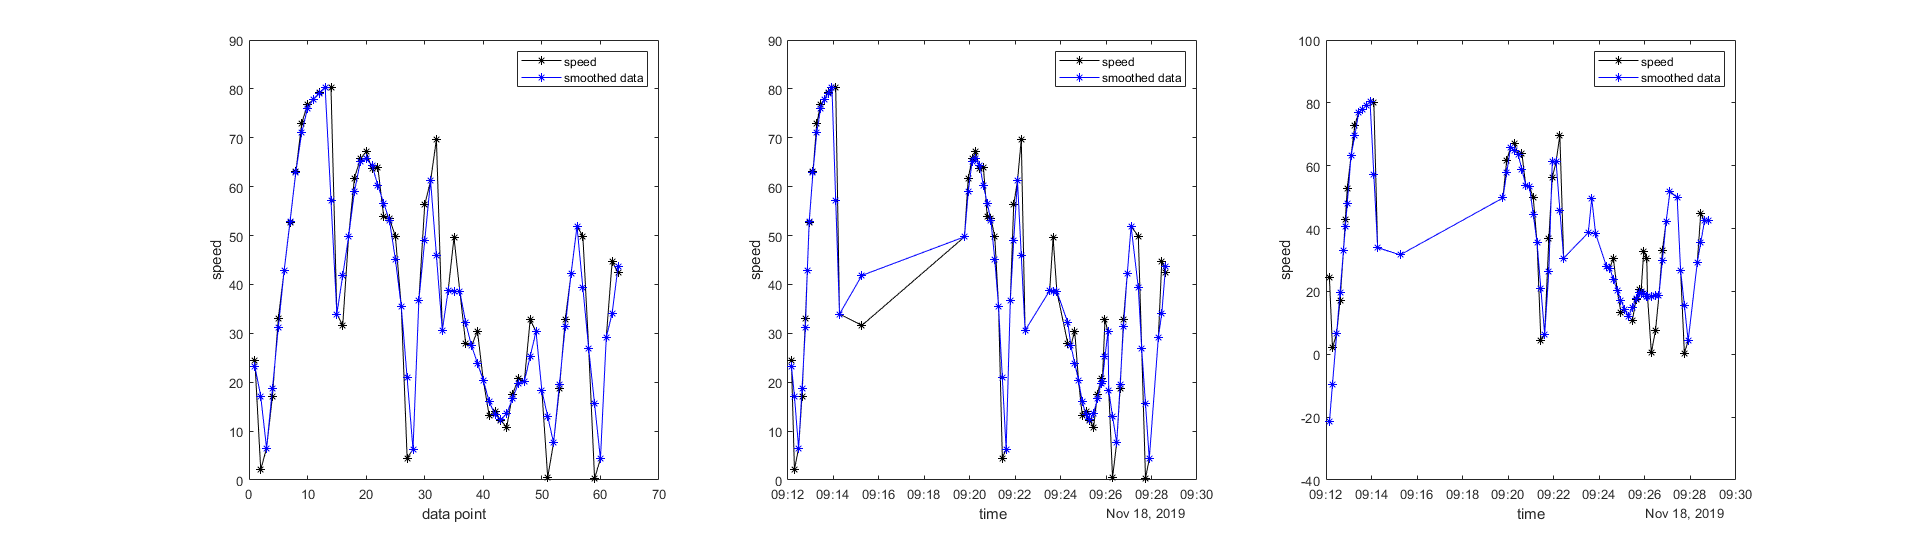

aa = osrm_data_sp(osrm_data_sp.arac_id == 'zzcxton' & osrm_data_sp.route_id == 200,:);


h = figure();
ax1 = subplot(1,3,1);

plot(ax1,aa.phy_speed,'-*k')
hold on
plot(ax1,aa.clean_speed,'-*b')
ylabel(ax1,'speed')
xlabel(ax1,'data point')
legend(ax1,'speed','smoothed data')



ax2 = subplot(1,3,2);
plot(ax2,aa.time,aa.phy_speed,'-*k')
hold on
plot(ax2,aa.time,aa.clean_speed,'-*b')
ylabel(ax2,'speed')
xlabel(ax2,'time')
legend(ax2,'speed','smoothed data')
set(h,'Units','normalized','Position',[0 0 1 0.5]);
deneme = smoothdata(aa.phy_speed,'rlowess',5 * median(diff(aa.time)),'SamplePoints',aa.time);

ax3 = subplot(1,3,3);
plot(ax3,aa.time,aa.phy_speed,'-*k')
hold on
plot(ax3,aa.time,deneme,'-*b')
ylabel(ax3,'speed')
xlabel(ax3,'time')
legend(ax3,'speed','smoothed data')

set(h,'Units','normalized','Position',[0 0 1 0.5]);



osrm_data_sp.delta_v =  osrm_data_sp.phy_speed - osrm_data_sp.clean_speed;
osrm_data_sp.delta_v_perc =  100 *  abs(osrm_data_sp.delta_v) ./ osrm_data_sp.phy_speed;
osrm_data_sp.delta_a =  osrm_data_sp.phy_acc - osrm_data_sp.smooth_speed_acc;
osrm_data_sp.delta_a_perc =  100 *  abs(osrm_data_sp.delta_a) ./ osrm_data_sp.smooth_speed_acc;

osrm_data_sp.rel_v = (osrm_data_sp.phy_speed - osrm_data_sp.clean_speed) ./ ((abs(osrm_data_sp.phy_speed) + abs(osrm_data_sp.clean_speed)) / 2);
osrm_data_sp.rel_a = (osrm_data_sp.phy_acc - osrm_data_sp.smooth_speed_acc) ./ ((abs(osrm_data_sp.phy_acc) + abs(osrm_data_sp.smooth_speed_acc)) / 2);


* = robus lowess operations

rule 1 = abs(100 x (phy_speed - *phy_speed) / *phy_speed) > 100

rule 2 = phy_acc - acc(*phy_speed) > 3

rule 3 = (relative) (phy_speed - speed) / (abs(phy_speed) + abs(*speed)) * 0.5 > 1

% osrm_data_sp.rule1 = false(size(osrm_data_sp,1),1);
% osrm_data_sp.rule2 = false(size(osrm_data_sp,1),1);
osrm_data_sp.rule1 = true(size(osrm_data_sp,1),1);
osrm_data_sp.rule2 = true(size(osrm_data_sp,1),1);
osrm_data_sp.rule3 = true(size(osrm_data_sp,1),1);

% osrm_data_sp.rule1(osrm_data_sp.speed > 200) = true;
osrm_data_sp.rule1(abs(osrm_data_sp.delta_v_perc) > 100) = false;
% osrm_data_sp.rule1(abs(osrm_data_sp.raw_acc)> 10) = false;
osrm_data_sp.rule2(abs(osrm_data_sp.delta_a) > 3) = false;
osrm_data_sp.rule3(abs(osrm_data_sp.rel_v) > 1.2) = false;

osrm_data_sp.filter2 = ~(~osrm_data_sp.rule1 | ~osrm_data_sp.rule2 | ~osrm_data_sp.rule3);

sum(~osrm_data_sp.filter2)

ans = 2265

osrm_data_sp.new_speed = osrm_data_sp.phy_speed;
osrm_data_sp.new_speed(~osrm_data_sp.filter2) = osrm_data_sp.clean_speed(~osrm_data_sp.filter2);

route_table = table;

[a,b] = findgroups(osrm_data_sp(:,{'arac_id','route_id'}));

route_table.arac_id = b.arac_id;
route_table.route_id = b.route_id;

route_table = sortrows(route_table,{'arac_id','route_id'});

%split and apply

route_table.st_start = NaN(size(route_table,1),1);
route_table.st_end = NaN(size(route_table,1),1);
route_table.time_start = NaT(size(route_table,1),1);
route_table.time_end = NaT(size(route_table,1),1);
route_table.time_elapsed = NaT(size(route_table,1),1) - NaT;
route_table.segment_id_start = NaN(size(route_table,1),1);
route_table.segment_id_end = NaN(size(route_table,1),1);
route_table.n_data = NaN(size(route_table,1),1);
route_table.filter_iqr = NaN(size(route_table,1),1);
route_table.filter_phy = NaN(size(route_table,1),1);
route_table.filter2 = NaN(size(route_table,1),1);
route_table.confidence = NaN(size(route_table,1),1);
route_table.dir = NaN(size(route_table,1),1);
route_table.time_delta_med = NaT(size(route_table,1),1) - NaT;


for i = 1:1:size(route_table,1)
    
    aux_index = (osrm_data_sp.arac_id == route_table.arac_id(i)) & (osrm_data_sp.route_id == route_table.route_id(i));
    
    route_table.st_start(i) = min(osrm_data_sp.distance_from_start(aux_index));
    route_table.st_end(i) = max(osrm_data_sp.distance_from_start(aux_index));
    route_table.time_start(i) = max(osrm_data_sp.time(aux_index));
    route_table.time_end(i) = min(osrm_data_sp.time(aux_index));
    route_table.time_elapsed(i) = max(osrm_data_sp.time(aux_index)) - min(osrm_data_sp.time(aux_index));
    route_table.time_delta_med(i) = median(diff(osrm_data_sp.time(aux_index)));
    route_table.segment_id_start(i) = min(osrm_data_sp.segment_id(aux_index));
    route_table.segment_id_end(i) = max(osrm_data_sp.segment_id(aux_index));
    route_table.n_data(i) = sum(aux_index);
    route_table.filter_iqr(i) = sum(~osrm_data_sp.filter(aux_index));
    route_table.filter_phy(i) = sum(~osrm_data_sp.filter_speed_phy(aux_index) |  ~osrm_data_sp.filter_acc_phy(aux_index));
    route_table.confidence(i) = min(osrm_data_sp.confidence(aux_index));
    route_table.dir(i) = min(osrm_data_sp.dir(aux_index));    
    route_table.filter2(i) = sum(~osrm_data_sp.filter2(aux_index));
end


route_table.route_len = route_table.st_end - route_table.st_start;
route_table.n_segment = route_table.segment_id_end - route_table.segment_id_start + 1;
route_table.data_segment = route_table.n_data ./ route_table.n_segment;

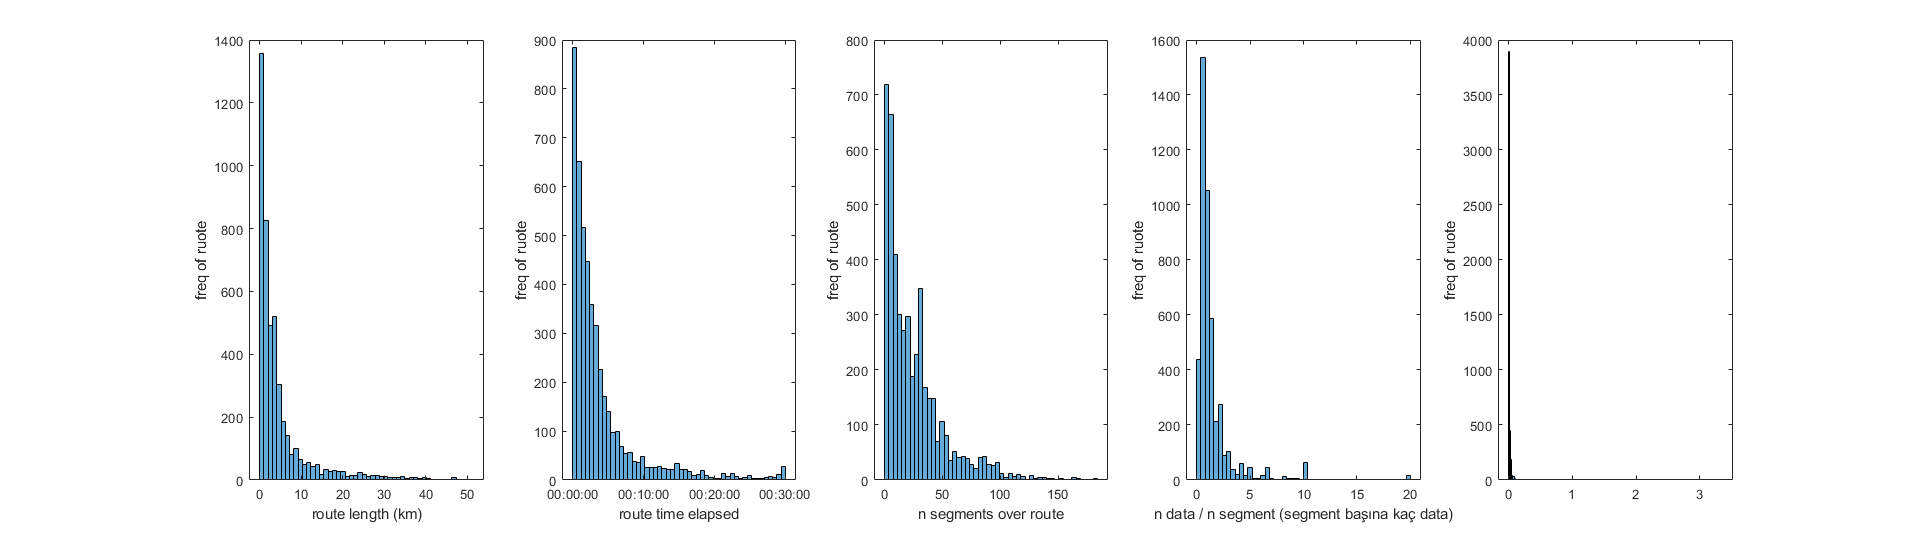

h=figure();

ax1 = subplot(1,5,1);
histogram(ax1,route_table.route_len * 1e-3,50)
ylabel(ax1, 'freq of ruote')
xlabel(ax1,'route length (km)')

ax2 = subplot(1,5,2);
histogram(ax2,route_table.time_elapsed,50)
ylabel(ax2, 'freq of ruote')
xlabel(ax2,'route time elapsed')

ax3 = subplot(1,5,3);
histogram(ax3,route_table.n_segment,50)
ylabel(ax3, 'freq of ruote')
xlabel(ax3,'n segments over route')

ax4 = subplot(1,5,4);
histogram(ax4,route_table.data_segment,50)
ylabel(ax4, 'freq of ruote')
xlabel(ax4,'n data / n segment (segment başına kaç data)')

ax5 = subplot(1,5,5);
histogram(ax5,route_table.n_data ./ route_table.route_len,200)
ylabel(ax5, 'freq of ruote')
% xlabel(ax5,'n data / n segment (segment başına kaç data)')

set(h,'Units','normalized','Position',[0 0 1 0.5]);

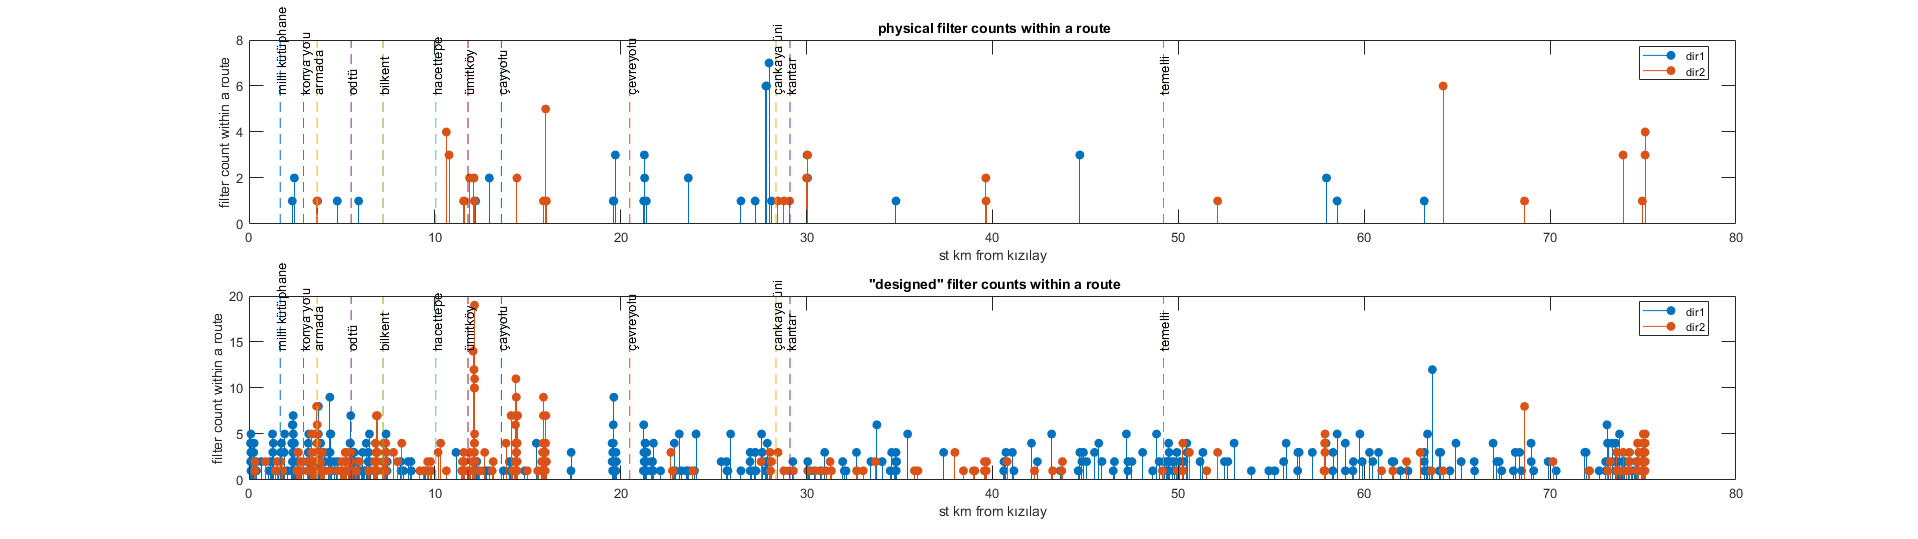

h = figure();
ax1 = subplot(2,1,1);
dir_chosen = 1;
index = route_table.dir == dir_chosen;
index2 = find(route_table(index,:).filter_phy);
stem(ax1, route_table(index,:).st_start(index2) * 1e-3, route_table(index,:).filter_phy(index2) ,'filled');
hold(ax1,'on')
dir_chosen = 2;
index = route_table.dir == dir_chosen;
index2 = find(route_table(index,:).filter_phy);
stem(ax1, corridor_length - route_table(index,:).st_start(index2) * 1e-3, route_table(index,:).filter_phy(index2) ,'filled');
legend(ax1,'AutoUpdate','off');
legend(ax1,'dir1','dir2','Location',"best");
title(' physical filter counts within a route');
xlabel('st km from kızılay')
ylabel('filter count within a route')
yLimits = get(ax1,'YLim');
dir_chosen = 1;
line(ax1,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax1, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), 0.7*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);



ax2 = subplot(2,1,2);
dir_chosen = 1;
index = route_table.dir == dir_chosen;
index2 = find(route_table(index,:).filter2);
stem(ax2, route_table(index,:).st_start(index2) * 1e-3, route_table(index,:).filter2(index2) ,'filled');
hold(ax2,'on')
dir_chosen = 2;
index = route_table.dir == dir_chosen;
index2 = find(route_table(index,:).filter2);
stem(ax2, corridor_length - route_table(index,:).st_start(index2) * 1e-3, route_table(index,:).filter2(index2) ,'filled');
legend(ax2,'AutoUpdate','off');
legend(ax2,'dir1','dir2','Location',"best");
title(' "designed" filter counts within a route');
xlabel('st km from kızılay')
ylabel('filter count within a route')
yLimits = get(ax2,'YLim');
dir_chosen = 1;
line(ax2,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax2, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), 0.7*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);
set(h,'Units','normalized','Position',[0 0 1 0.5]);

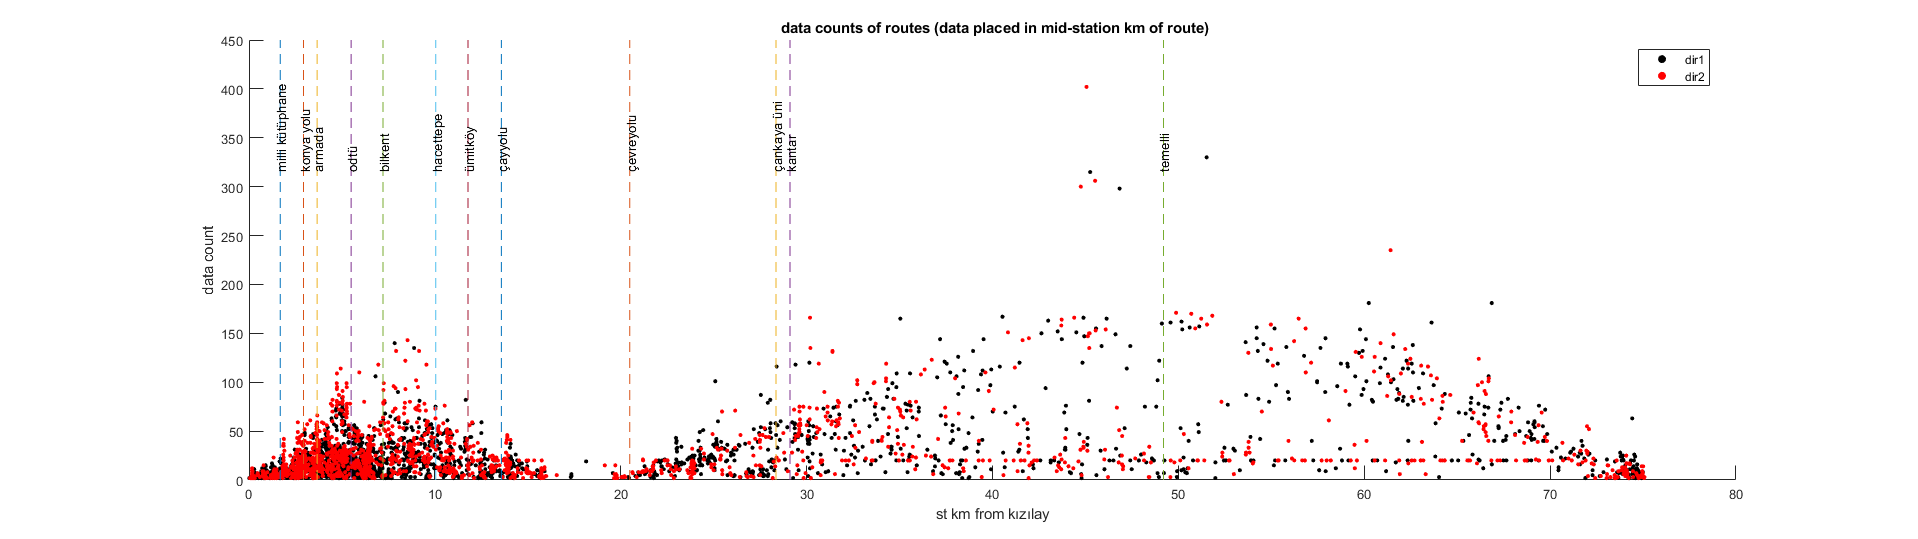

h = figure();
ax1 = subplot(1,1,1);
dir_chosen = 1;
index = route_table.dir == dir_chosen;
scatter(ax1, 0.5 * (route_table(index,:).st_start + route_table(index,:).st_end) * 1e-3, route_table(index,:).n_data,10,'black','filled');
hold(ax1,'on')
dir_chosen = 2;
index = route_table.dir == dir_chosen;
% index2 = find(route_table(index,:).filter_phy);
scatter(ax1, corridor_length - 0.5 * (route_table(index,:).st_start + route_table(index,:).st_end) * 1e-3, route_table(index,:).n_data,10,'red','filled');
legend(ax1,'AutoUpdate','off');
legend(ax1,'dir1','dir2','Location',"best");
title(' data counts of routes (data placed in mid-station km of route)');
xlabel('st km from kızılay')
ylabel('data count')
yLimits = get(ax1,'YLim');
dir_chosen = 1;
line(ax1,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax1, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), 0.7*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);

set(h,'Units','normalized','Position',[0 0 1 0.5]);

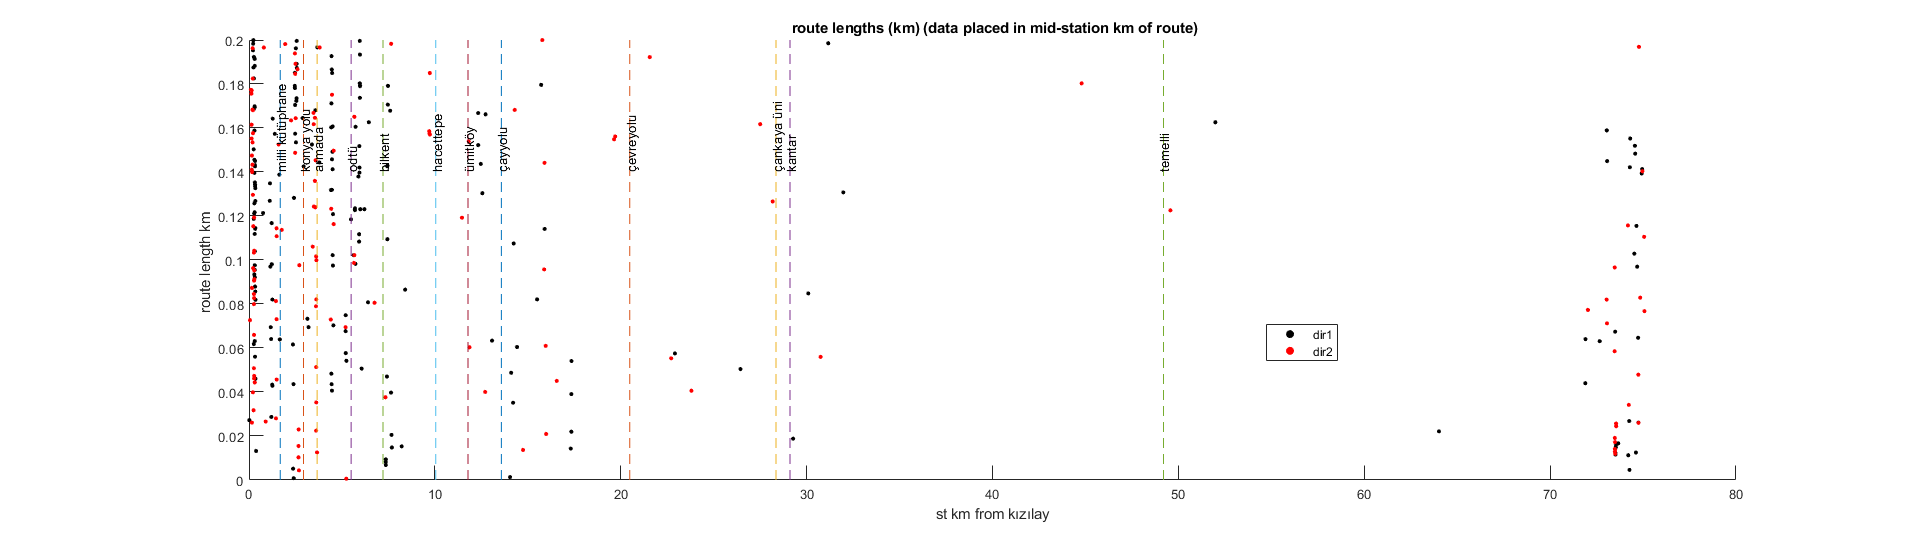

h = figure();
ax1 = subplot(1,1,1);
dir_chosen = 1;
index = route_table.dir == dir_chosen;
scatter(ax1, 0.5 * (route_table(index,:).st_start + route_table(index,:).st_end) * 1e-3, route_table(index,:).route_len * 1e-3,10,'black','filled');
hold(ax1,'on')
dir_chosen = 2;
index = route_table.dir == dir_chosen;
scatter(ax1, corridor_length - 0.5 * (route_table(index,:).st_start + route_table(index,:).st_end) * 1e-3, route_table(index,:).route_len * 1e-3,10,'red','filled');
legend(ax1,'AutoUpdate','off');
legend(ax1,'dir1','dir2','Location',"best");
title(' route lengths (km) (data placed in mid-station km of route)');
xlabel('st km from kızılay')
ylabel('route length km ')
ylim([0 0.2])
yLimits = get(ax1,'YLim');
dir_chosen = 1;
line(ax1,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax1, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), 0.7*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);

set(h,'Units','normalized','Position',[0 0 1 0.5]);

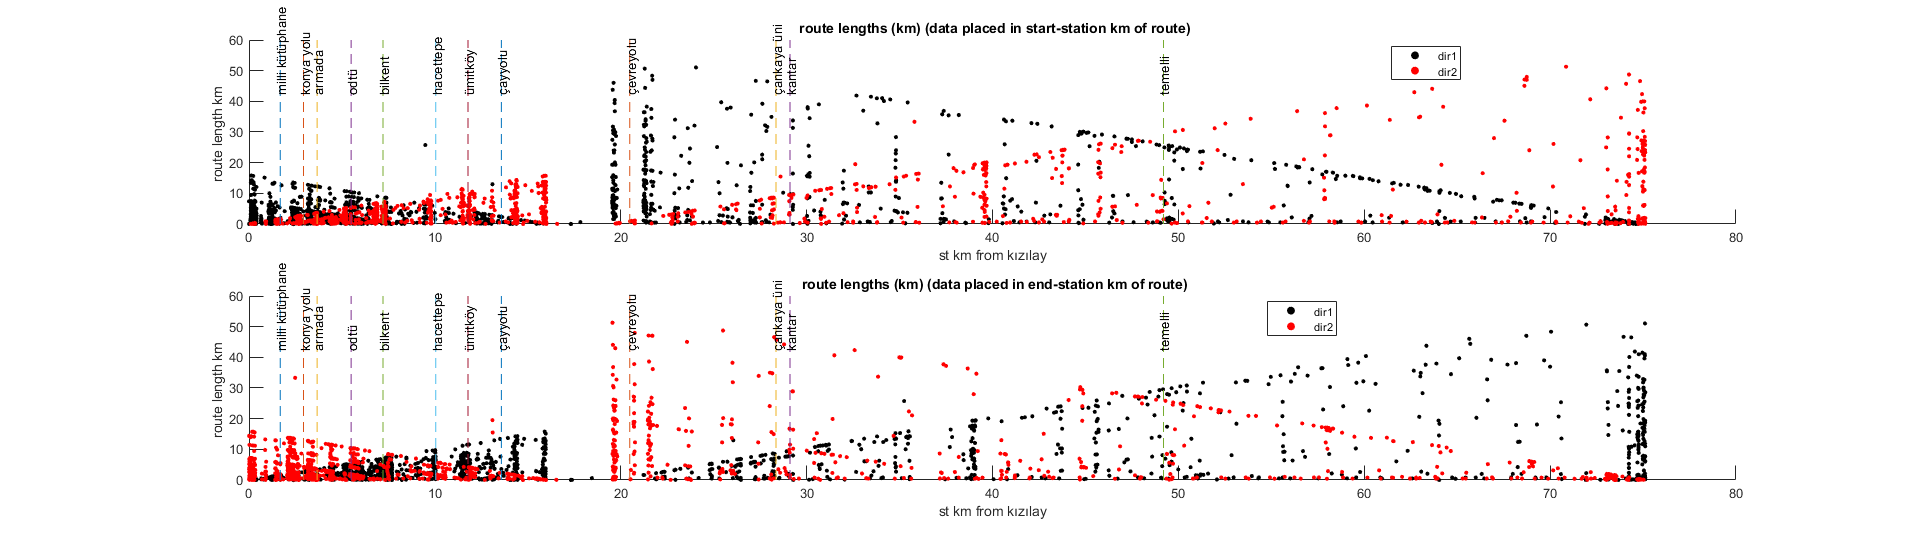

h = figure();
ax1 = subplot(2,1,1);
dir_chosen = 1;
index = route_table.dir == dir_chosen;
scatter(ax1, route_table(index,:).st_start * 1e-3, route_table(index,:).route_len * 1e-3,10,'black','filled');
hold(ax1,'on')
dir_chosen = 2;
index = route_table.dir == dir_chosen;
scatter(ax1, corridor_length - route_table(index,:).st_start *1e-3, route_table(index,:).route_len * 1e-3,10,'red','filled');
legend(ax1,'AutoUpdate','off');
legend(ax1,'dir1','dir2','Location',"best");
title(' route lengths (km) (data placed in start-station km of route)');
xlabel('st km from kızılay')
ylabel('route length km ')
yLimits = get(ax1,'YLim');
dir_chosen = 1;
line(ax1,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax1, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), 0.7*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);

ax1 = subplot(2,1,2);
dir_chosen = 1;
index = route_table.dir == dir_chosen;
scatter(ax1, route_table(index,:).st_end * 1e-3, route_table(index,:).route_len * 1e-3,10,'black','filled');
hold(ax1,'on')
dir_chosen = 2;
index = route_table.dir == dir_chosen;
scatter(ax1, corridor_length - route_table(index,:).st_end *1e-3, route_table(index,:).route_len * 1e-3,10,'red','filled');
legend(ax1,'AutoUpdate','off');
legend(ax1,'dir1','dir2','Location',"best");
title(' route lengths (km) (data placed in end-station km of route)');
xlabel('st km from kızılay')
ylabel('route length km ')
yLimits = get(ax1,'YLim');
dir_chosen = 1;
line(ax1,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax1, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), 0.7*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);



set(h,'Units','normalized','Position',[0 0 1 0.5]);

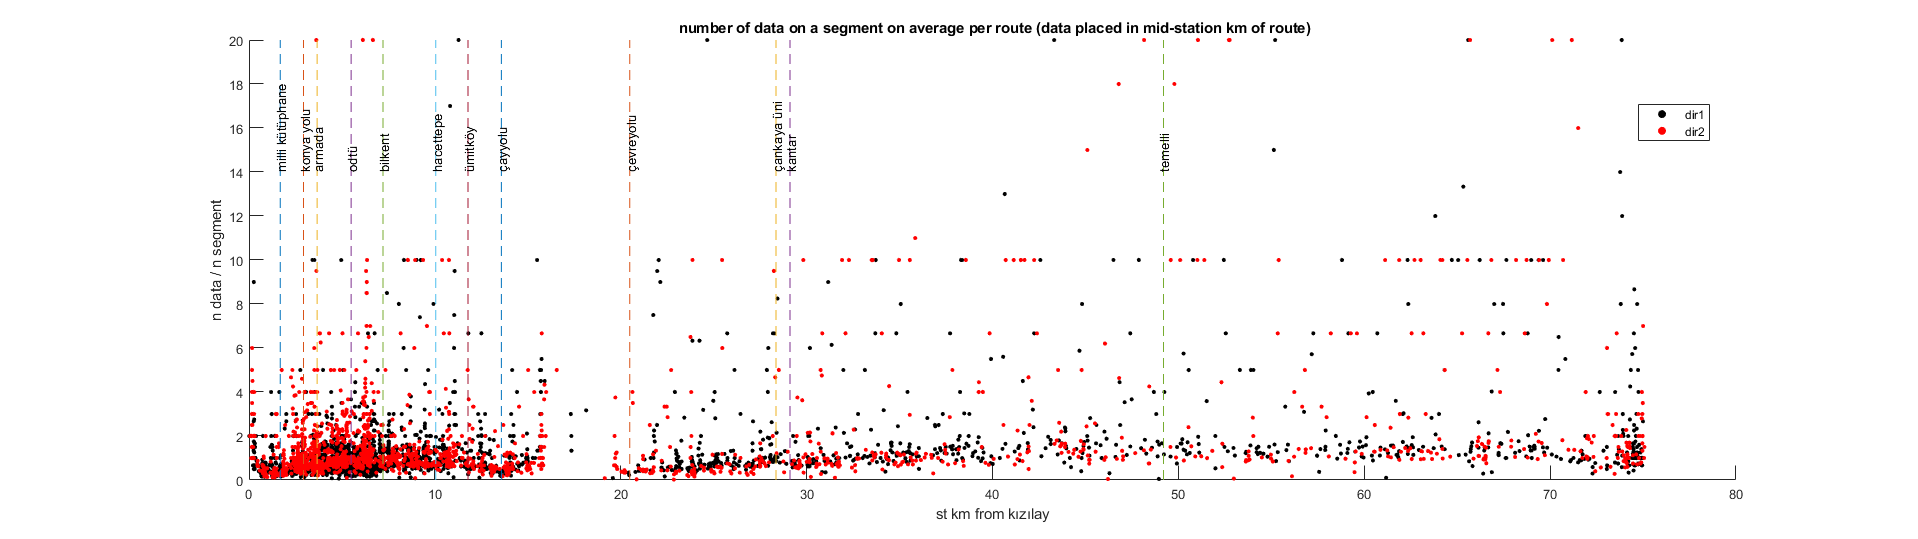

h = figure();
ax1 = subplot(1,1,1);
dir_chosen = 1;
index = route_table.dir == dir_chosen;
scatter(ax1, 0.5 * (route_table(index,:).st_start + route_table(index,:).st_end) * 1e-3, route_table.data_segment(index) ,10,'black','filled');
hold(ax1,'on')
dir_chosen = 2;
index = route_table.dir == dir_chosen;
scatter(ax1, corridor_length - 0.5 * (route_table(index,:).st_start + route_table(index,:).st_end) * 1e-3, route_table.data_segment(index),10,'red','filled');
legend(ax1,'AutoUpdate','off');
legend(ax1,'dir1','dir2','Location',"best");
title(' number of data on a segment on average per route (data placed in mid-station km of route)');
xlabel('st km from kızılay')
ylabel('n data / n segment')
yLimits = get(ax1,'YLim');
dir_chosen = 1;
line(ax1,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax1, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), 0.7*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);

set(h,'Units','normalized','Position',[0 0 1 0.5]);

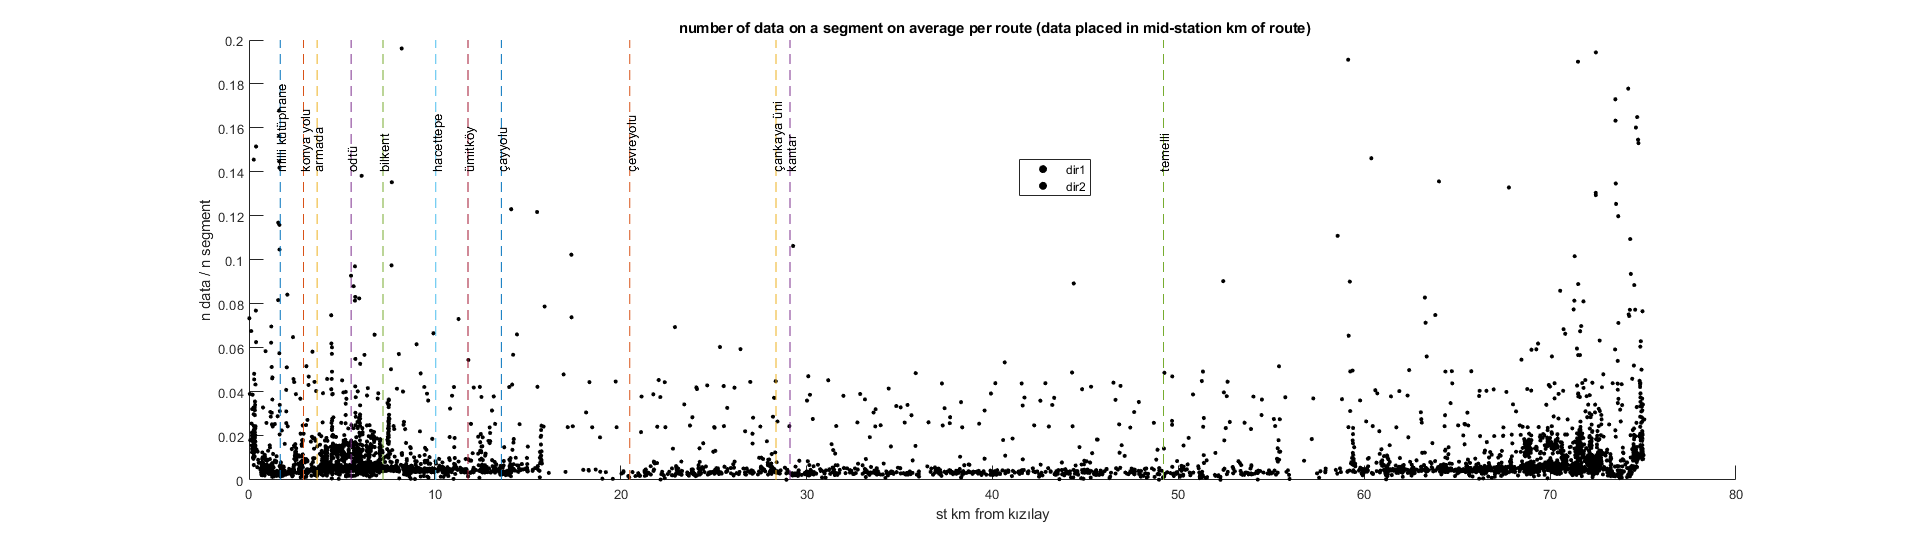

h = figure();
ax1 = subplot(1,1,1);
dir_chosen = 1;
index = route_table.dir == dir_chosen;
scatter(ax1, 0.5 * (route_table(index,:).st_start + route_table(index,:).st_end) * 1e-3, route_table.n_data(index) ./ route_table.route_len(index) ,10,'black','filled');
hold(ax1,'on')
dir_chosen = 2;
index = route_table.dir == dir_chosen;
scatter(ax1, 0.5 * (route_table(index,:).st_start + route_table(index,:).st_end) * 1e-3, route_table.n_data(index) ./ route_table.route_len(index) ,10,'black','filled');
legend(ax1,'AutoUpdate','off');
legend(ax1,'dir1','dir2','Location',"best");
title(' number of data on a segment on average per route (data placed in mid-station km of route)');
xlabel('st km from kızılay')
ylabel('n data / n segment')
ylim(ax1, [0 0.2])
yLimits = get(ax1,'YLim');
dir_chosen = 1;
line(ax1,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
text(ax1, 1e-3*markers.distance_from_start(markers.dir == dir_chosen), 0.7*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);

set(h,'Units','normalized','Position',[0 0 1 0.5]);

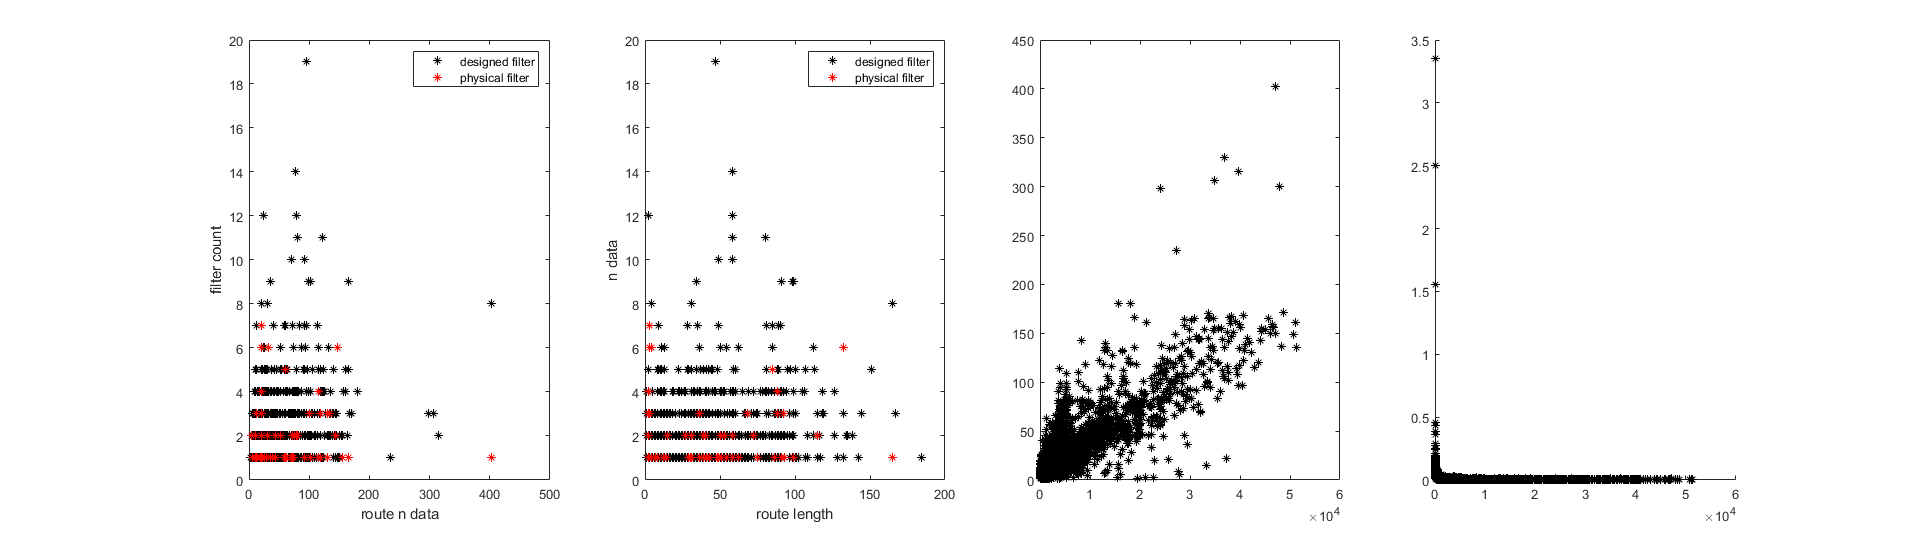

h = figure();

ax1 = subplot(1,4,1);
index = find(route_table.filter2);
plot(ax1, route_table.n_data(index), route_table.filter2(index) ,'*k');
hold(ax1,'on')
index = find(route_table.filter_phy);
plot(ax1, route_table.n_data(index), route_table.filter_phy(index) ,'*r');
legend(ax1, 'designed filter', 'physical filter')
xlabel(ax1, 'route n data')
ylabel(ax1, 'filter count')


ax2 = subplot(1,4,2);
index = find(route_table.filter2);
plot(ax2, route_table.n_segment(index), route_table.filter2(index) ,'*k');
hold(ax2,'on')
index = find(route_table.filter_phy);
plot(ax2, route_table.n_segment(index), route_table.filter_phy(index) ,'*r');
legend(ax2, 'designed filter', 'physical filter')
xlabel(ax2, 'route n segment')
ylabel(ax2, 'filter count')


ax3 = subplot(1,4,3);
% index = find(route_table.filter2);
plot(ax3, route_table.route_len, route_table.n_data ,'*k');
% hold(ax2,'on')
% index = find(route_table.filter_phy);
% plot(ax2, route_table.n_segment(index), route_table.filter_phy(index) ,'*r');
% legend(ax2, 'designed filter', 'physical filter')
xlabel(ax2, 'route length')
ylabel(ax2, 'n data')

ax4 = subplot(1,4,4);
scatter(ax4, route_table.route_len, route_table.n_data ./ (route_table.route_len),'*k');

set(h,'Units','normalized','Position',[0 0 1 0.5]);

route_table = sortrows(route_table,{'n_segment','data_segment'},{'ascend','descend'});

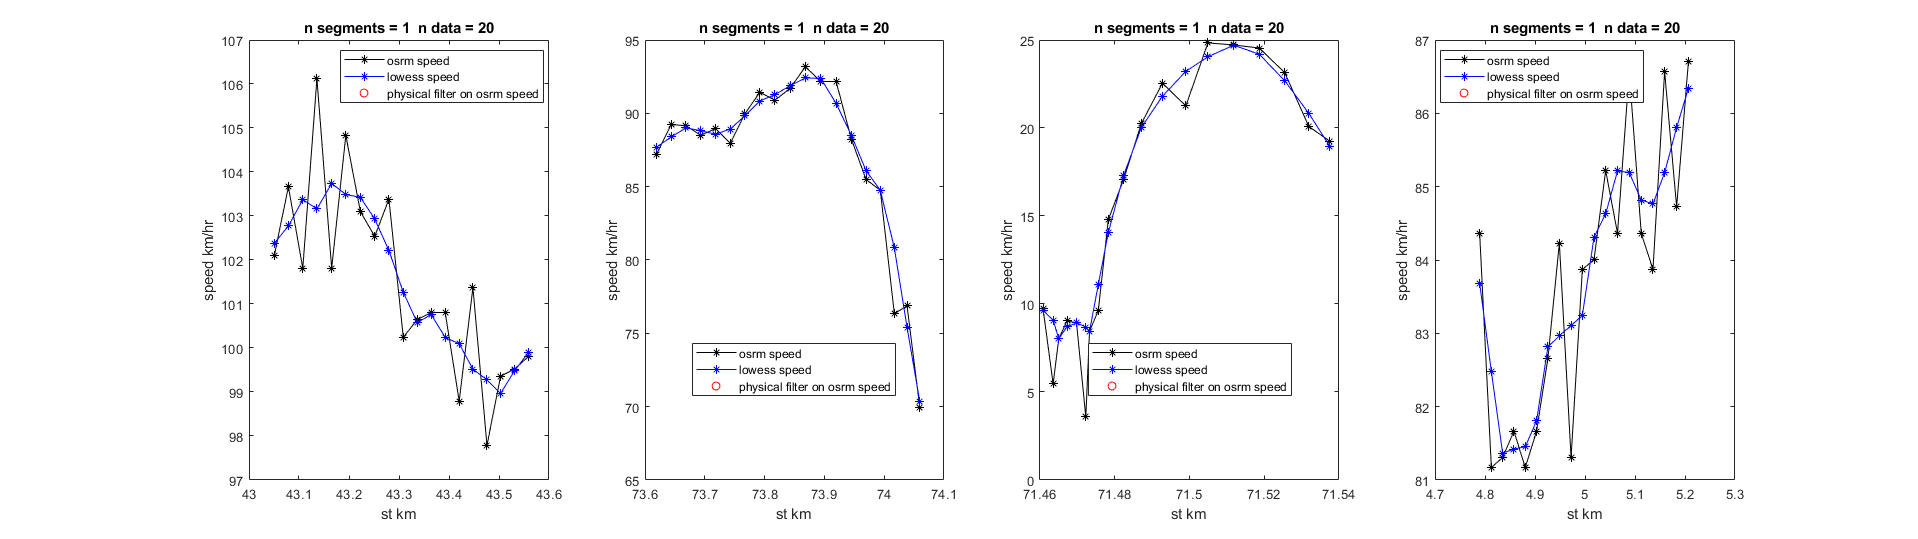

h = figure();

ax1 = subplot(1,4,1);
i = 1;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')


ax1 = subplot(1,4,2);
i = 2;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')


ax1 = subplot(1,4,3);
i = 3;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')

ax1 = subplot(1,4,4);
i = 4;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')



set(h,'Units','normalized','Position',[0 0 1 0.5]);

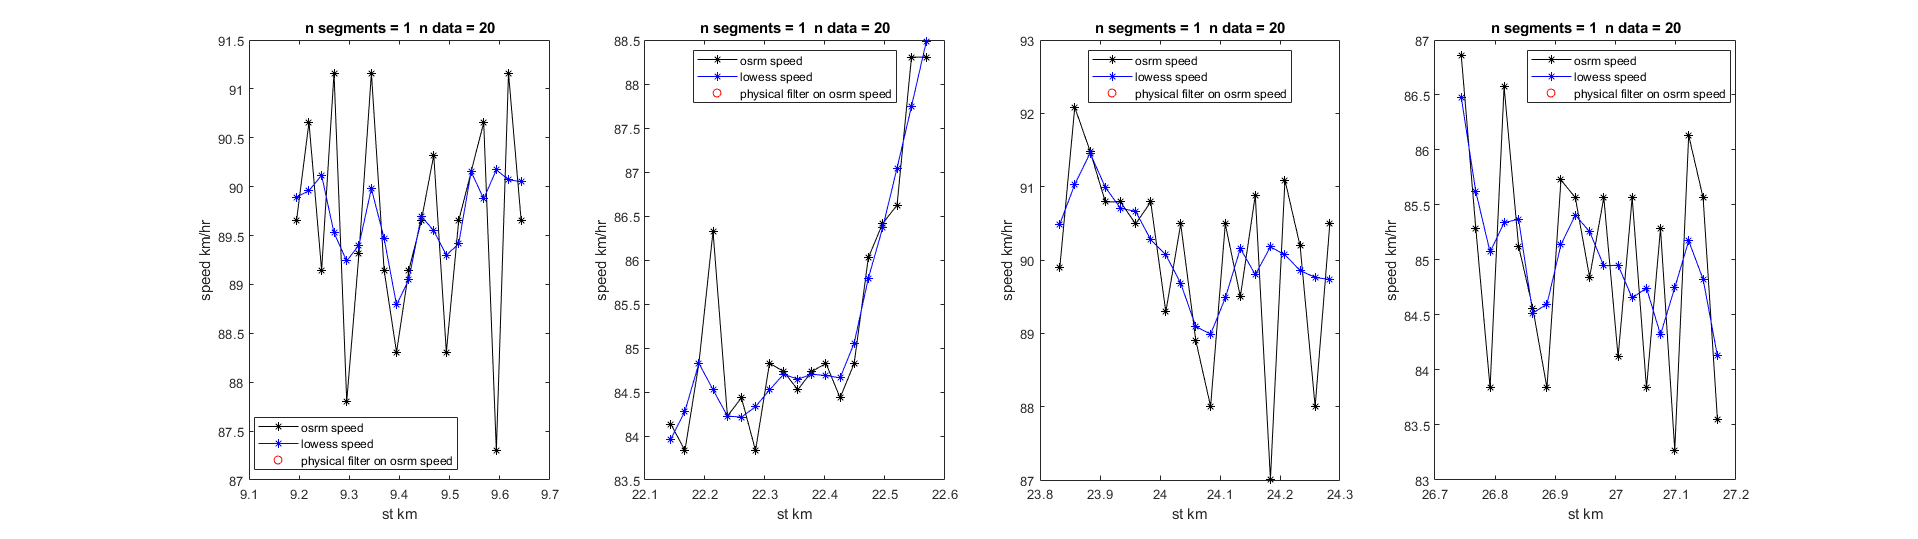

h = figure();

ax1 = subplot(1,4,1);
i = 5;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')


ax1 = subplot(1,4,2);
i = 6;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')


ax1 = subplot(1,4,3);
i = 7;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')

ax1 = subplot(1,4,4);
i = 8;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')



set(h,'Units','normalized','Position',[0 0 1 0.5]);

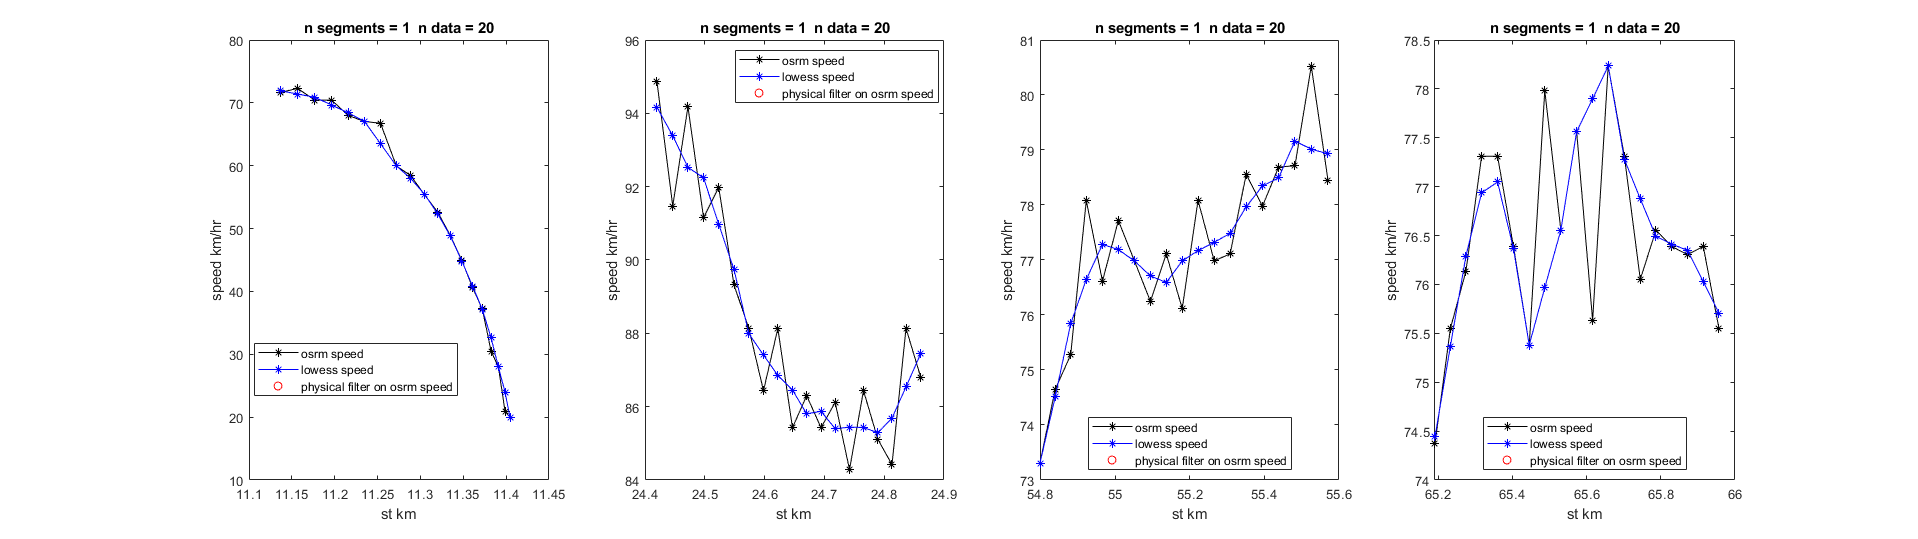

h = figure();

ax1 = subplot(1,4,1);
i = 9;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')


ax1 = subplot(1,4,2);
i = 10;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')


ax1 = subplot(1,4,3);
i = 11;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')

ax1 = subplot(1,4,4);
i = 12;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')



set(h,'Units','normalized','Position',[0 0 1 0.5]);

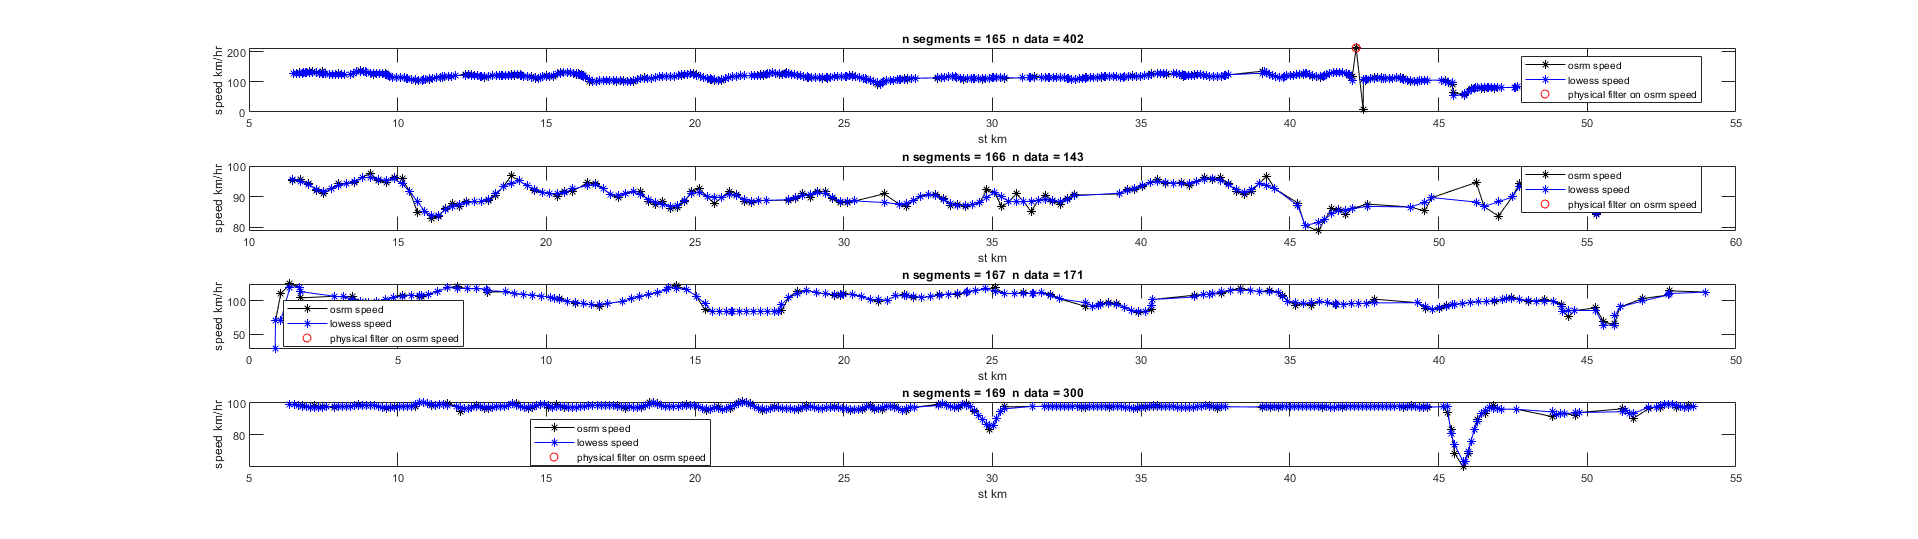

h = figure();

ax1 = subplot(4,1,1);
i = 4660;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')


ax1 = subplot(4,1,2);
i = 4661;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')


ax1 = subplot(4,1,3);
i = 4662;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')

ax1 = subplot(4,1,4);
i = 4663;
arac_id = route_table.arac_id(i);
route_id = route_table.route_id(i);
aux_index = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id);
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.speed(aux_index), '-*k');
hold(ax1,'on')
plot(ax1, osrm_data_sp.distance_from_start(aux_index) * 1e-3, osrm_data_sp.clean_speed(aux_index), '-*b');
hold(ax1,'on')
aux_index2 = (osrm_data_sp.arac_id == arac_id) & (osrm_data_sp.route_id == route_id) & (~osrm_data_sp.filter_speed_phy | ~osrm_data_sp.filter_acc_phy);
scatter(ax1, osrm_data_sp.distance_from_start(aux_index2) * 1e-3, osrm_data_sp.speed(aux_index2), 'red',"o");
title(ax1, ['n segments = ',num2str(route_table.n_segment(i)) , '  n data = ', num2str(route_table.n_data(i))])
ylabel(ax1,'speed km/hr')
xlabel(ax1,'st km')
legend(ax1, 'osrm speed', 'lowess speed' , 'physical filter on osrm speed','Location','Best')



set(h,'Units','normalized','Position',[0 0 1 0.5]);

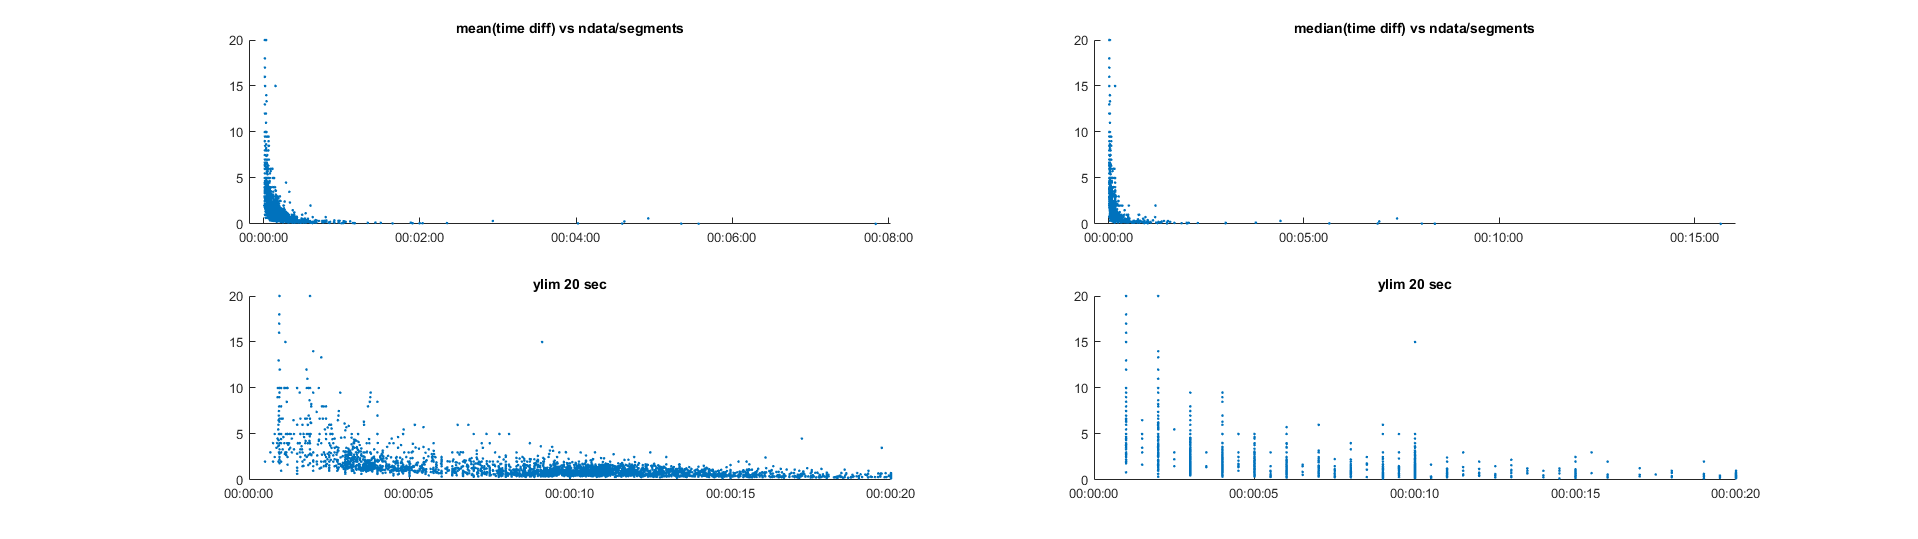

h=figure();

ax1 = subplot(2,2,1);
scatter(ax1, route_table.time_elapsed ./ route_table.n_data, route_table.data_segment,4,'filled');
title(ax1, 'mean(time diff) vs ndata/segments')
ax2 = subplot(2,2,2);
scatter(ax2, route_table.time_delta_med, route_table.data_segment,4,'filled');
title(ax2, 'median(time diff) vs ndata/segments')

ax3 = subplot(2,2,3);
scatter(ax3, route_table.time_elapsed ./ route_table.n_data, route_table.data_segment,4,'filled');
xlim(ax3,[0 seconds(20)])
title(ax3, 'ylim 20 sec')
ax4 = subplot(2,2,4);
scatter(ax4, route_table.time_delta_med, route_table.data_segment,4,'filled');
xlim(ax4,[0 seconds(20)])
title(ax4, 'ylim 20 sec')
set(h,'Units','normalized','Position',[0 0 1 0.5]);

% time_1 = datetime({'2019-11-18 08:00:00'});
% time_2 = datetime({'2019-11-18 10:00:00'});
% aux_time = time_1:minutes(15):time_2;
% dir_chosen = 1;
% h=figure();
% for i=1:1:length(aux_time)-1
%     ax1 = subplot(length(aux_time)-1,1,i);
%     index = route_table.time_start >= aux_time(i) & route_table.time_end < aux_time(i+1);
% %     boxchart(ax1,double(aug_data.segment_id(index)) ,aug_data.speed(index),"MarkerStyle",'.','MarkerColor','red')
%     scatter(ax1, corridor_length - 0.5 * (route_table(index,:).st_start + route_table(index,:).st_end) * 1e-3, route_table.data_segment(index),10,'red','filled');
% %     title(ax1,['AUG ', datestr(aux_time(i)), '---', datestr(aux_time(i+1)),'  ','direction = ', num2str(dir_chosen), 'segment id vs speed boxplot ndata = ',num2str(sum(index))])
% %     ylim(ax1,[0 200])
%     yLimits = get(ax1,'YLim');
%     line(ax1,[markers.segment_id(markers.dir == dir_chosen),markers.segment_id(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
%     ax1.XLim = [min(double(aug_data.segment_id(index))) , max(double(aug_data.segment_id(index)))];
% end
% text(ax1, double(markers.segment_id(markers.dir == dir_chosen)), -0.1*repmat(yLimits(1),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);
% ax1.XLim = [min(double(aug_data.segment_id(index))) , max(double(aug_data.segment_id(index)))];
% set(h,'Units','normalized','Position',[0 0 1 1]);